### lab8 Problem 1 - Euler's Method

format long e;
h = 0.2;
t = 1:h:3;

y_true = @(t) 2*(t ./ (1 - 2.*t));
dydt = @(t) (1./t).*(y_true(t).^2 + y_true(t));

y_approx = FWD_Euler(dydt(t), t, h, y_true(1));

**True Solution v. Approximation**

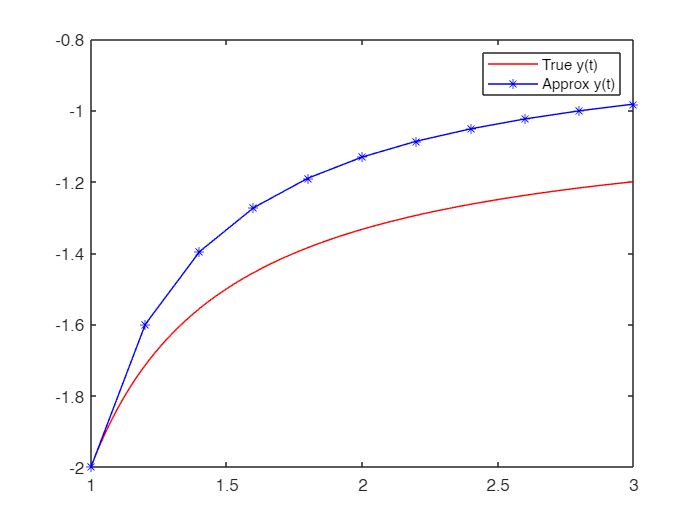

x_linspace = linspace(1, 3, 1000); 
plot(x_linspace, y_true(x_linspace), "r-", t, y_approx, "b*-");
legend("True y(t)", "Approx y(t)")

**Absolute Error Chart**

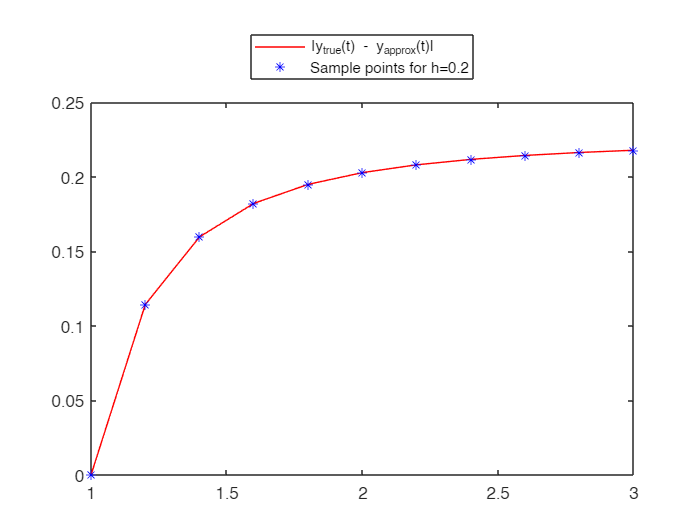

err = abs(y_true(t) - y_approx);
plot(t, err, "r-", t, err, "b*");
legend("|y_{true}(t) - y_{approx}(t)|", "Sample points for h=0.2", "Location", "northoutside")

**Observations**

The error increases as time goes on. The increasing error is likely because we only utilize 11 points between an interval of 2 units. When I use h=0.01, the actual solution and approximation are very close, with the absolute error being just under 0.01. 

Because we use a larger h-value, we lose a lot of information critical to an accurate solution. This is proven correct for this example as our initial approximation at $y_1$is slightly removed from its true value, which generates a lot of error for the rest of the graph. 

**Forward Euler's method Function**

function y = FWD_Euler(dydt, t, h, initial_value)
    % dydt - the ODE
    % t - vector that contains each sampled point
    % h - length between t values |t(i + 1) - t(i)|
    % initial_value - initial value 
    N = length(t);
    y = zeros(1, N); % empty vec
    
    y(1) = initial_value;

    for i = 2:N
        y(i) = y(i-1) + h*dydt(i-1);
    end
    
end